## Flight Control Law Design and Application 

### Term Project Part II: Stability Augmentation and Longitudinal Control

**Introduction**

This Matlab livescript is designed for the term project of the course 'Flight Control Law Design and Application'. It comprises all tasks to be done during the second half of Part I of the term project.he script is designed such that it will provide you with information, specific tasks, and checks to verify your solutions. Further, this script will be used by us to verify your results at the end of Part I of the term project. 

**Do's and Don'ts**

In order to use this livescript successfully, you have to fullfill the given **Tasks** (blockwise) in the given order. It is recommended to run the code sections one by one and to valide your results with the implemented checks before advancing. Otherwise, required results for subsequent parts might not be available. Sections can be executed individually with the 'Run Section' Button above.

When running a code section, warnings and error messages might be displayed within this script analog to the usual output in the command window. Use these warnings/errors to correct your solutions if necessary.

Again, all of the tasks in this script refer to the 'AircraftModel_LonMot.slx' model that you worked on during Part I. That means, all **Tasks** of Part I *must be completed before advancing* to the **Tasks** in this script.

In Part II, you will design controllers for the longitudinal motion of the aircraft.

**Preparation and Session Start**

This task will prepare Part II of the term project. Futher, this code will run several parameter scripts and will load several variables, structs, etc. into your Matlab workspace. Provided this, the 'AircraftModel_LonMot.slx' model is executable. 

**Task 1: **prepare for Part II of the term project

- copy all files (and folders) from the '1_TermProject_Part_I' folder into the newly provided '2_TermProject_Part_II' folder

- load all required variables, structs, etc. into your Matlab workspace

- to do so, run this section (keyboard short cut: cntr + enter)

clear
clc

addpath('1_Model_LongitudinalMotion')
addpath('1_Model_LongitudinalMotion\1_Checks\')
addpath('2_Model_TrimLinearize')
addpath('3_LongitudinalControl')

run("AircraftParameters_LonMot.m");
run("AircraftParameters_Addition_LonMot.m");

load("TrimState_1_LinearLonModel.mat");

**Stability Augmentation System I**

Recall from the lecture that flight control laws are ultimately tested by human pilots. That is, pilots have the last word on whether the flight characteristics of an aircraft are acceptable. This qualitative assessment is called *handling qualities *of a particular aircraft. In the early days of human flight, the handling qualities could only be modified through changes of the mechanical linkage from pilot inputs to the control surfaces, or by modifying the (aerodynamic) aircraft design itself (e.g. by varying elevator size or lever arms, etc.). Modern aircraft (except for most general aviation aircraft) comprise a digital fly-by-wire control system. As such, control inputs can be issued by computers on top of the pilot inputs to improve the flight characteristics of the aircraft. This is called a stability augmentation system (SAS). A very useful measure for flight characteristics is the *thumb print criterion*, see the figure below. It characterizes the handling qualities of an aircraft based on the location of the eigenvalues linked to the short period mode. In a first step towards the full flight control system, you will design a SAS to improve the handling qualities of your aircraft.

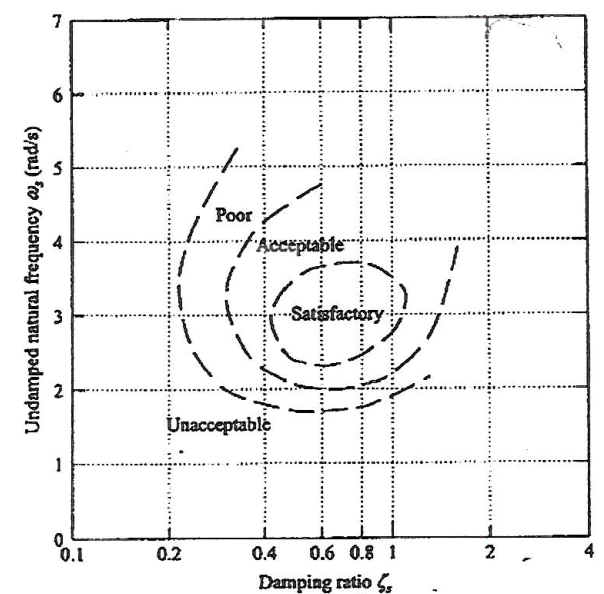

**Task 2: **check the characteristics of your aircraft in terms of the thumb print criterion 

- uncommend the code section below

- recall the eigenvalues of the short period mode from Part I

- identify the poles linked to the short period model and define 'idx_sp' accordingly

- evaluate the eigenfrequency and the damping ratio of the short period mode w.r.t. the thumb print criterion. Are the characteristics of the aircraft "Satisfactory", "Acceptable" or "Poor"?

[omega_n,zeta] = damp(LinearLonModel)

omega_n =     0.0005
    0.1061
    0.1061
    2.5692
    2.5692


zeta =     1.0000
    0.0509
    0.0509
    0.4119
    0.4119


% --------------------start of your code -------------------------- %

idx_sp = [4 5]; % define the indizes within omega_n that correspond to the of the eigenvalues linked to the short period mode, e.g. [1 2]
    
% --------------------end of your code ---------------------------- %

Regardless of the outcome of the evaluation, we intend to achieve an eigenfrequency of $\omega_n^{\star}=3\,\text{rad/s}$ and a damping ration of $\zeta^{\star}=\,0.7$ for the short perion mode to be right in the middle of the "Satisfactory"-region of the thumb print criterion. To achieve this, a SAS is required that feeds back the current angle of attack $\alpha$ and the pitch rate $q$, see the figure below. We will compute the feedback gain 'F' to apply direct pole placement for the plant model 'P'. In a first step, we will use the short period approximation model 'TrimState_1_SPModel.mat' from Part I.

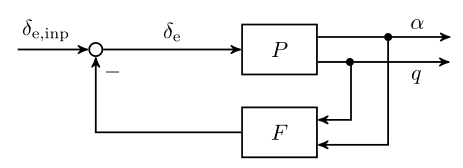

**Task 3: **design a SAS that modifies the longitudinal dynamics of the aircraft

- uncomment the code section below

- load the 'TrimState_1_SPModel.mat' into your workspace

- use the *Bass-Gura formula *from the lecture notes (Eq. 5.12 - 5.15) to compute the state feedback control law 'F_bg'

- compute the coefficients $a_0,a_1,a_0^{\star}$ and $a_1^{\star}$ (use code, don't type in the coefficients by hand)

- Note that the short period model from Part I has two inputs ('cmd_de' and 'cmd_dt') but 'F' shall only affect the elevator deflection command - what does this imply for the B-matrix to be used in the Bass-Gura forumla?

- **save the changes you've made within this livescript**

load("TrimState_1_SPModel.mat");
% --------------------start of your code -------------------------- %

omega_nstar = 3;
zeta_star = 0.7;

a0 = (omega_n(4)^2);
a1 = 2*zeta(4)*omega_n(4);

a0_star = (omega_nstar)^2;
a1_star = 2*zeta_star*omega_nstar;

F_bg = [a1_star-a1, a0_star-a0]*[1, -a1; 0, 1]/[SPModel.B(:,1), SPModel.A*SPModel.B(:,1)];

% --------------------end of your code ---------------------------- %

Alternatively, you can use Matlabs `place` command to calculate the feedback gains to place the short period eigenvalues at specified locations. Note that `place` requires as many pole locations to be specified as there are rows in the A matrix. Now recall that the 'LinearLonModel' has more than the two states $\alpha$ and $q$ and thus the A matrix has more than two rows. Hence, if you use the 'LinearLonModel' additional pole locations (for the phugoid poles and the altitude pole) need to be specified as well. Further, if all poles are to be defined, then probably all states will be used for feedback to achieve the desired pole locations (check this for yourself by using the 'LinearLonModel' for the `place` command). From the lecture we know, that the short period poles can be modified via $\alpha$ and $q$ feedback only. Moreover, the other poles are, in general, only little affected. Hence, the $2^{nd}$ order 'SPModel' is sufficient to compute the feedback gain 'F'. 

- uncomment the code section below

- calculate the eigenvalues corresponding to $\omega^\star_n = 3$ and $\zeta^{\star} = 0.7$ (recall that $\zeta = -\sigma/\omega_{n}$ and $\omega_{n} = |\lambda|$ for the eigenvalue $\lambda = \sigma + j\omega$)  and compute a vector '`p`' that contains them

- compute the feedback gain 'F' using Matlabs `place` command. Get the syntax of the `place` command from the Matlab documentation. 

- Again: Note that the short period model from Part I has two inputs ('cmd_de' and 'cmd_dt') but 'F' shall only affect the elevator deflection command - what does this imply for the B-matrix to be used in the `place` command?

- close the feedback loop around the **'LinearLonModel' **to incorporate the SAS into your linear aircraft model. Use the `feedback` command and review the Matlab documentation to unterstand its syntax. Hint: Check the order of $\alpha$ and $q$ and be sure to apply the correct gain to the correct output.

- name the stability augmented system 'LinearLonModel_SAS_1'.

- compare the computed feedback gains obtained with the *Bass-Gura* formula and the `place` command using the subsequent check section. They should be identical.

- compare the natural frequencies and the damping ratios of the "original" short period mode and the modified short period mode using the subsequent check section.

- **save the changes you've made within this livescript**

% --------------------start of your code -------------------------- %

sigma = - zeta_star*omega_nstar;
w     = sqrt(omega_n(4)^2-sigma^2);
p = roots([1 a1_star a0_star]);
F = place(SPModel.A,SPModel.B(:,1),p);
LinearLonModel;
F_dummy = [F(2), zeros(1,6), F(1); zeros(1,8)]

F_dummy =    -0.2133         0         0         0         0         0         0   -0.0494
         0         0         0         0         0         0         0         0


LinearLonModel_SAS_1 = feedback(LinearLonModel, F_dummy);

% --------------------end of your code ---------------------------- %
clear sigma w p

**Check**

fprintf(['feedback gains using place:      ' num2str(F) '\nfeedback gains using Bass-Gura:  ' num2str(F_bg)])

feedback gains using place:      -0.049449     -0.2133
feedback gains using Bass-Gura:  -0.049449     -0.2133

[omega_ncheck,zeta_check] = damp(LinearLonModel_SAS_1);
table({'original short period mode:'; 'modified short period mode:'} , [zeta(idx_sp(1));zeta_check(idx_sp(1))], [omega_n(idx_sp(1));omega_ncheck(idx_sp(1))], 'VariableNames', {'    ';'Damping Ratio';'Natural Frequency'})   % display all eigenvalues, damping factors and natural frequencies

ans = 2×3 table
                                       Damping Ratio    Natural Frequency
    _______________________________    _____________    _________________

    {'original short period mode:'}       0.41186            2.5692      
    {'modified short period mode:'}       0.70047            2.9979      



clear omega omega_n omega_star omega_nstar omega_ncheck zeta zeta_star zeta_check F_bg F p idx_sp

**Influence of Actuation Systems and Time Delays**

Recall from Part I that both, the 'SPModel' and the 'LinearLonModel' do not include the dynamics of the actuation and propulsion systems. This section is solely designed to provide you some additional insight into their influence. That is, you can add additional delay into the system and modify the dynamics of the elevator. Both parameters affect the root loci of the system. The root loci for $q$ and $\alpha$ feedback will be displayed below.

**Task 4: **investigate the influence of the actuation system and time delays on the root loci

- add additional delay of up to $0.2\,\text{s}$ using the first slider below. Note that the "original" delay of the actuation system 'Actuators.Delays.tau_de' is already included (see AircraftParameters_Addition_LonMot.m)

- modify the pole location of the actuator dynamics using the second slider. Note that a larger negative value of the A matrix correspronds to faster actuator dynamics

- compare the root loci of the 'SPModel' with and without the actuator dyanamics for the pitch rate and angle of attack 

- think for yourself: what will happen to the short period pole locations, given a fixed feedback gain of the SAS but different time delays and actuator dynamics? 

run("AircraftParameters_Addition_LonMot.m"); % load default parameters
add_delay =0.1; % use the slider to specify an additional delay
Actuators.Act_e.A = Actuators.Act_e.A +1; % increase or decrease the natural eigenfrequency of the actuation system by using the slider 
Actuators.Act_e.A % output A matrix to investigate pole modification

ans = -20.0202

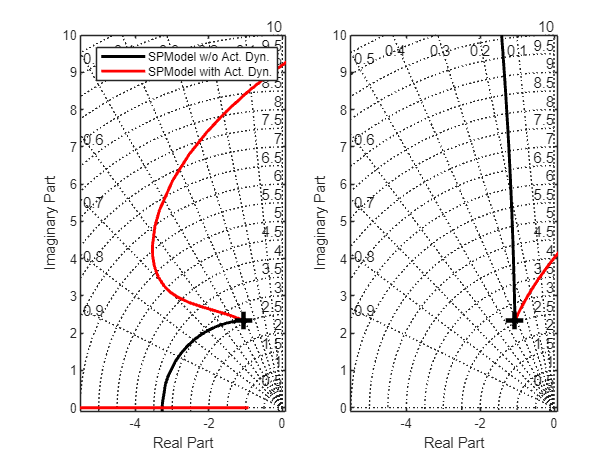

Actuators.Act_e.B = -Actuators.Act_e.A; % ensure a steady state gain of 1

Td = exp(-add_delay*tf('s')); % transfer function representing the additional(!) delay
InvestModel = SPModel*blkdiag(Actuators.Act_e*Td,1); % augment the SPModel with the dynamics of the actuation system and the additional time delay

figure(320); clf
subplot(1,2,1), rl1 = my_rlocus(SPModel,'q',1,'k'); hold on, rl2 = my_rlocus(InvestModel,'q',1,'r'); legend([rl1(1),rl2(1)],{'SPModel w/o Act. Dyn.','SPModel with Act. Dyn.'})
subplot(1,2,2), [~] = my_rlocus(SPModel,'alpha',1,'k'); hold on, [~] = my_rlocus(InvestModel,'alpha',1,'r'); 

clear InvestModel Td add_delay Actuators rl1 rl2

**Augment the Linear Models with Actuator Dynamics**

From the last section we saw that time delays and actuator dynamics can have a significant influence on the required feedback gains of a SAS. Hence, we have to inlcude them into the design process in order to compute a suitable SAS that actually achieves the desired (closed-loop) plant dynamics.

**Task 5: **incorporate the actuator and engine dynamics into the linear aircraft model

- create a new state space model called 'ActPropDyn' including the actuator ('Actuators.Act_e') and propulsion system dynamics ('Propulsion.Act_t') by using the `append` command of Matlab

- define the output and state names to be 'de' and 'X_P' for the elevator deflection and the thrust force, resp.

- define the state units of 'ActPropDyn' appropriately  

- load both, the 'SPModel' and the 'LinearLonModel' from Part I into your workspace

- augment the 'SPModel' and the 'LinearLonModel' with the actuator and propulsion system dynamics via proper multiplication of the state space models

- rename the newly created models to 'SPModel_Aug' and 'LinearLonModel_Aug'. Check all names and units for all states, inputs and outputs

- save the augmented linear models to 'TrimState_1_LinearLonModel_Aug.mat' and 'TrimState_1_SPModel_Aug.mat'. Save them into the '3_LongitudinalControl' folder

run("AircraftParameters_Addition_LonMot.m");
load("TrimState_1_SPModel.mat");
load("TrimState_1_LinearLonModel.mat");
% --------------------start of your code -------------------------- %
ActPropDyn = append(Actuators.Act_e, Propulsion.Act_t);
%ActPropDyn.OutputName = ['de' 'X_P'];
%ActPropDyn.StateName = ['de' 'X_P'];
%ActPropDyn.StateUnit = ['rad' 'N'];

SPModel_Aug = SPModel*ActPropDyn;
LinearLonModel_Aug = LinearLonModel*ActPropDyn;

% --------------------end of your code ---------------------------- %

Note that you could obtain the same result by linearizing the augmented nonlinear simulation model (e.g. with the help of the 'Model Linearizer' app) using the trim point of **Task 14** of Part I.

**Task 6:** compare the linear models using Bode plots 

- use the provided function `my_bode_plot` to compare the Bode plots for the 'LinearLonModel_Aug', 'SPModel_Aug' and 'SPModel'  (ensure that the 'my_bode_plot.m' is in the active path; this function is not part of Matlab and written for this class. Matlab has the function `bode` to generate a similar plot.) - take a look into the function to explore its mechanisms

- type code in the subsequent code section to plot the frequency responses for all three linear models from commanded elevator deflection to $q$, $\alpha$ and $n_z$ simultaneously

- compare the results and check for yourself if the frequency responses of the individual models, and the differences between them are resonable

- **save the changes you've made within this livescript**

figure(300); clf
% --------------------start of your code -------------------------- %
input = ['cmd_de']

input = 'cmd_de'

outputs= {'q', 'alpha', 'n_z'}

outputs = 1×3 cell array
    {'q'}    {'alpha'}    {'n_z'}


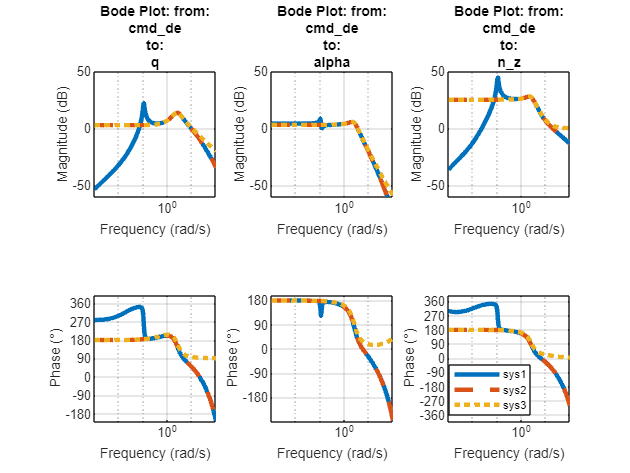

my_bode_plot(outputs, input, LinearLonModel_Aug, SPModel_Aug, SPModel)


% --------------------end of your code ---------------------------- %
clf

**Check**

ActPropDyn

ActPropDyn =
 
  A = 
            de     X_P
   de   -21.02       0
   X_P       0    -0.5
 
  B = 
        cmd_de  cmd_dt
   de    21.02       0
   X_P       0     0.5
 
  C = 
         de  X_P
   de     1    0
   X_P    0    1
 
  D = 
        cmd_de  cmd_dt
   de        0       0
   X_P       0       0
 
  Input delays (seconds): 0.04  0.5 
 
Continuous-time state-space model.


ActPropDyn.StateUnit

ans = 2×1 cell array
    {0×0 char}
    {0×0 char}


**Stability Augmentation System II**

run("AircraftParameters_Addition_LonMot.m");
ControlLaws.LonMot.SAS.F_q = -0.17986

ControlLaws = struct with fields:
    LonMot: [1×1 struct]



ControlLaws.LonMot.SAS.F_q = ss(-0.17986)

ControlLaws = struct with fields:
    LonMot: [1×1 struct]


Recall from **Task 4** that the root loci of the short period approximation model with and without actuator dynamics differ. Hence, the feedback gain 'F' calculated in **Task 3** might no longer place the short period poles as intended. As we want to design the SAS for the "true" aircraft, we choose that model for controller design that represents the system best. From **Task 6** we see that the 'SPModel_Aug' and the 'LinearLonModel_Aug' do not differ in the frequency range of the short period mode. That is, both models are suitable for SAS controller design. Note that both models now also include the time delay of the actuation system.

**Task 6:** design a SAS feedback controller 

- rerun the 'AircraftParameters_Addition_LonMot.m' Matlab script to erase possible changes you've made w.r.t. to the actuation system during **Task 4**

- type `help controlSystemDesigner` into your command window to check the syntax of the `controlSystemDesigner` command

Remark: The `controlSystemDesigner` command opens the 'Control System Designer' app of Matlab. Unfortunately, specifying the desired transfer function that you want to investigate within the 'Control System Designer' app is cumbersome. Hence, we recommend to use the `controlSystemDesigner` command directly instead of opening the 'Control System Designer' app and then specify the plant model etc.. The `controlSystemDesigner` command is identical to the fomer (and still functioning) `sisotool` command.

- choose either the 'SPModel_Aug' or the 'LinearLonModel_Aug' for the follwing design step

- use the `controlSystemDesigner` command to investigate the transfer function from elevator input to pitch rate.

- edit the control architecture within the 'Control System Designer' app via the 'Edit Architecture' option to match the architecture of a SAS, see the figure below.

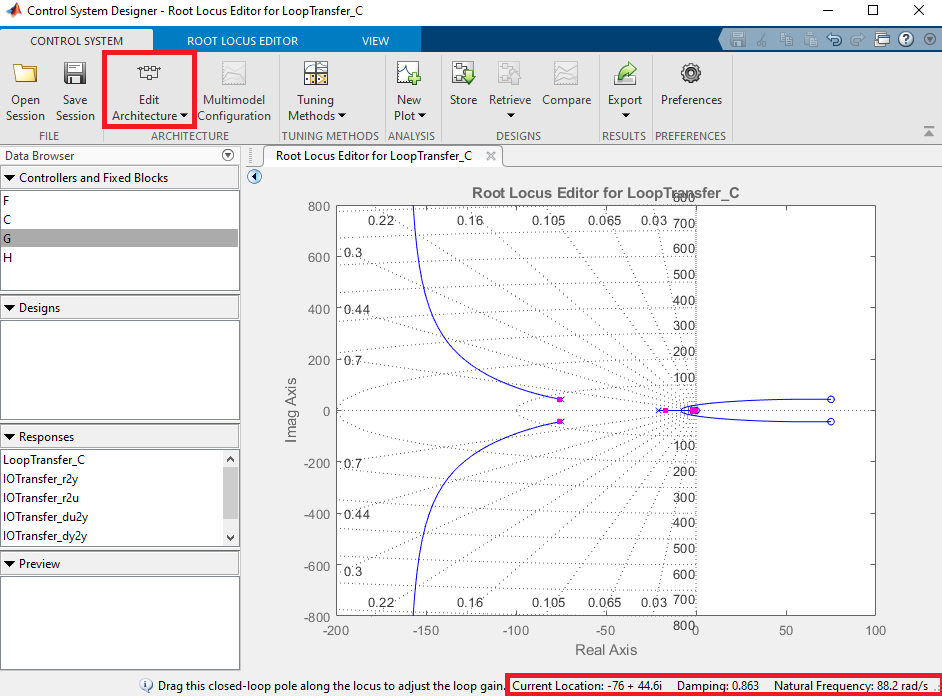

- modify the short period mode pole location by 'drag and drop' within the 'Root Locus Editor' (see the figure above)

- think about the required sign for the controller. A good mnemonic is to think about the reaction of the output to a given input. E.g. a positive elevator deflection leads to a negative pitch rate, so a negative sign for the controller gain is required. Apply this mnemonic to all following controller designs to determine the sign of the P-gain. You can adjust the sign by editing the compensator block 'C' in the controlSystemDesigner.

- verify that you are affecting the short period poles (e.g. compare the damping ratios and frequencies to the ones form the damp command).

- try to achieve $\omega^\star_n = 3$ and $\zeta^{\star} = 0.7$. Both, the natural frequency and the damping ratio are displayed in the bottom right corner of the 'Control System Designer' - note that minor deviations are insignificant as this is a qualitative approach and model uncertainties are inevitable. It might not be possible to achieve $\omega^\star_n = 3$ and $\zeta^{\star} = 0.7$ depending on your flight condition or group's individual aircraft characteristics. Try to find a "satisfactory" solution according to the thumb print criterion in that case. You could also consider additional angle of attack feedback (see lecture notes section 5.5), but we will not consider this option in the following.

- read off the controller gain 'C' and save it as 'F_q' in the following struct: 'ControlLaws.LonMot.SAS' 

- create a state space model of the same name (and thus overwrite 'F_q') of the controller from 'F_q' using the `ss` command and define input/output names and units. Note that the controller has direct feedthrough only, i.e., it has no states.

- save the entire  'ControlLaws' struct into a .mat-file named 'ControlLaws.mat'. Save it into the '3_LongitudinalControl' folder.

- is an additional alpha loop necessary or did the pitch rate feedback (pitch damper) provide a feasible solution?

**Check**

load ControlLaws.mat
ControlLaws.LonMot.SAS.F_q

ans =
 
  D = 
            u1
   y1  -0.1799
 
Static gain.
Model Properties


ControlLaws.LonMot.SAS.F_q.InputUnit

ans = 1×1 cell array
    {'rad/s'}


ControlLaws.LonMot.SAS.F_q.OutputUnit

ans = 1×1 cell array
    {'-'}


clear ans

**Task 7: **close the SAS feedback loop and compare results

- close the SAS feedback loop for both, the 'SPModel_Aug' and the 'LinearLonModel_Aug' (independent of the model you chose for the design) using the `feedback` command. Make sure that the loop connects the correct model output to the correct model input - Hint: either use the correct indizes or use the 'names' option of the `feedback` command

- name the newly created models 'SPModel_SAS' and 'LinearLonModel_SAS', respectively and save them to 'TrimState_1_LinearLonModel_SAS.mat' and 'TrimState_1_SPModel_SAS.mat'. Save them into the '3_LongitudinalControl' folder

- check the closed loop short period mode pole locations with the help of the subsequent check section - Note that a $2^{nd}$ order Padé approximation is applied to approximate the time delays of the system

- compare the short period mode pole locations for the open loop 'LinearLonModel', the 'LinearLonModel_SAS' and the 'SPModel_SAS' 

F_dummy = [zeros(1,7),-0.17986 ; zeros(1,8)];
LinearLonModel_SAS = feedback(LinearLonModel_Aug, F_dummy)

LinearLonModel_SAS =
 
  A = 
                 ?           ?           ?           ?           ?          de         X_P
   ?     -0.009033       11.76      -9.414      -9.784  -2.083e-05           0       2.728
   ?    -0.0006107     -0.9668      0.9599   -0.005422   8.002e-06    -0.07428   -0.001095
   ?      0.003614      -5.689      -1.152           0  -1.895e-06      -9.752    -0.09414
   ?             0           0           1           0           0           0           0
   ?       0.07213      -130.2           0       130.5           0           0           0
   de     -0.00209       3.771           0           0           0      -21.02           0
   X_P           0           0           0           0           0           0        -0.5
 
  B = 
        cmd_de  cmd_dt
   ?         0       0
   ?         0       0
   ?         0       0
   ?         0       0
   ?         0       0
   de    21.02       0
   X_P       0     0.5
 
  C = 
                   ?           ?        

SPModel_SAS = feedback(SPModel_Aug, F_dummy)

SPModel_SAS =
 
  A = 
                ?          ?         de        X_P
   ?      -0.9716     0.9625   -0.07428   -0.00225
   ?       -5.702     -1.145     -9.752   -0.09702
   de       3.779  -0.001086     -21.02          0
   X_P          0          0          0       -0.5
 
  B = 
        cmd_de  cmd_dt
   ?         0       0
   ?         0       0
   de    21.02       0
   X_P       0     0.5
 
  C = 
                   ?           ?          de         X_P
   q       -0.005323           1           0           0
   u          -7.489      0.6815           0           0
   w           130.3     0.01169           0           0
   Theta       0.865     -0.1465           0           0
   gamma     -0.1345     -0.1462           0           0
   Alt        -13.44       5.369           0           0
   n_z         12.84      0.4939      0.9883     0.01457
   alpha      0.9996  -0.0002873           0           0
 
  D = 
          cmd_de  cmd_dt
   q           0       0
   u           0 

**Check**

load TrimState_1_LinearLonModel
load TrimState_1_SPModel_SAS
load TrimState_1_LinearLonModel_SAS  
damp(LinearLonModel)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -4.59e-04                 1.00e+00       4.59e-04         2.18e+03    
 -5.40e-03 + 1.06e-01i     5.09e-02       1.06e-01         1.85e+02    
 -5.40e-03 - 1.06e-01i     5.09e-02       1.06e-01         1.85e+02    
 -1.06e+00 + 2.34e+00i     4.12e-01       2.57e+00         9.45e-01    
 -1.06e+00 - 2.34e+00i     4.12e-01       2.57e+00         9.45e-01    


damp(pade(LinearLonModel_SAS,2))

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -4.61e-04                 1.00e+00       4.61e-04         2.17e+03    
 -5.59e-03 + 1.07e-01i     5.21e-02       1.07e-01         1.79e+02    
 -5.59e-03 - 1.07e-01i     5.21e-02       1.07e-01         1.79e+02    
 -5.00e-01                 1.00e+00       5.00e-01         2.00e+00    
 -9.84e-01 + 2.70e+00i     3.43e-01       2.87e+00         1.02e+00    
 -9.84e-01 - 2.70e+00i     3.43e-01       2.87e+00         1.02e+00    
 -6.00e+00 + 3.46e+00i     8.66e-01       6.93e+00         1.67e-01    
 -6.00e+00 - 3.46e+00i     8.66e-01       6.93e+00         1.67e-01    
 -2.12e+01                 1.00e+00       2.12e+01         4.72e-02    
 -7.50e+01 + 4.33e+01i     8.66e-01       8.66e+01         1.33e

damp(pade(SPModel_SAS,2))

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -5.00e-01                 1.00e+00       5.00e-01         2.00e+00    
 -9.84e-01 + 2.70e+00i     3.43e-01       2.87e+00         1.02e+00    
 -9.84e-01 - 2.70e+00i     3.43e-01       2.87e+00         1.02e+00    
 -6.00e+00 + 3.46e+00i     8.66e-01       6.93e+00         1.67e-01    
 -6.00e+00 - 3.46e+00i     8.66e-01       6.93e+00         1.67e-01    
 -2.12e+01                 1.00e+00       2.12e+01         4.72e-02    
 -7.50e+01 + 4.33e+01i     8.66e-01       8.66e+01         1.33e-02    
 -7.50e+01 - 4.33e+01i     8.66e-01       8.66e+01         1.33e-02    


**SAS Implementation**

After you designed the SAS, you will now implement this first control law into the nonlinear aircraft simulation model. First, you'll augment the nonlinear simulation model.

**Task 8:**  augment the nonlinear simulation model

- open the 'AircraftModel_LonMot.slx' model and ensure that it is executable

- open the 'Auxiliary_Models.slx' model from the '3_LongitudinalControl' project folder

- include multiple blocks to reach the state as shown in the figure below:

- copy the 'Flight Controls' subsystem into the nonlinear aircraft model and connect it as shown in the figure below

- implement the 'Aero Noise' and 'EoM Noise' subsystems from the 'Auxiliary_Models.slx' model

- add the 'Test Sequences' subsystem from the 'Auxiliary_Models.slx' model and create a signal 'Inp' as shown in the figure below - use a 'mux' block from the Simulink library and connect the 'Inp' signal to the 'Flight Controls' subsystem

- add a 'To Workspace' block from the Simulink library that computes the 'out.inp_check' struct and connect it to the 'Inp' signal

- add a second  'To Workspace' block from the Simulink library that computes the 'out.aero_check' struct and connect it to the 'Aero' signal

- connect the wind signal from the 'Test Sequences' subsystem to the appropriate wind input

- optional: add the 'Visualization' block from the 'Auxiliary_Models.slx' model

           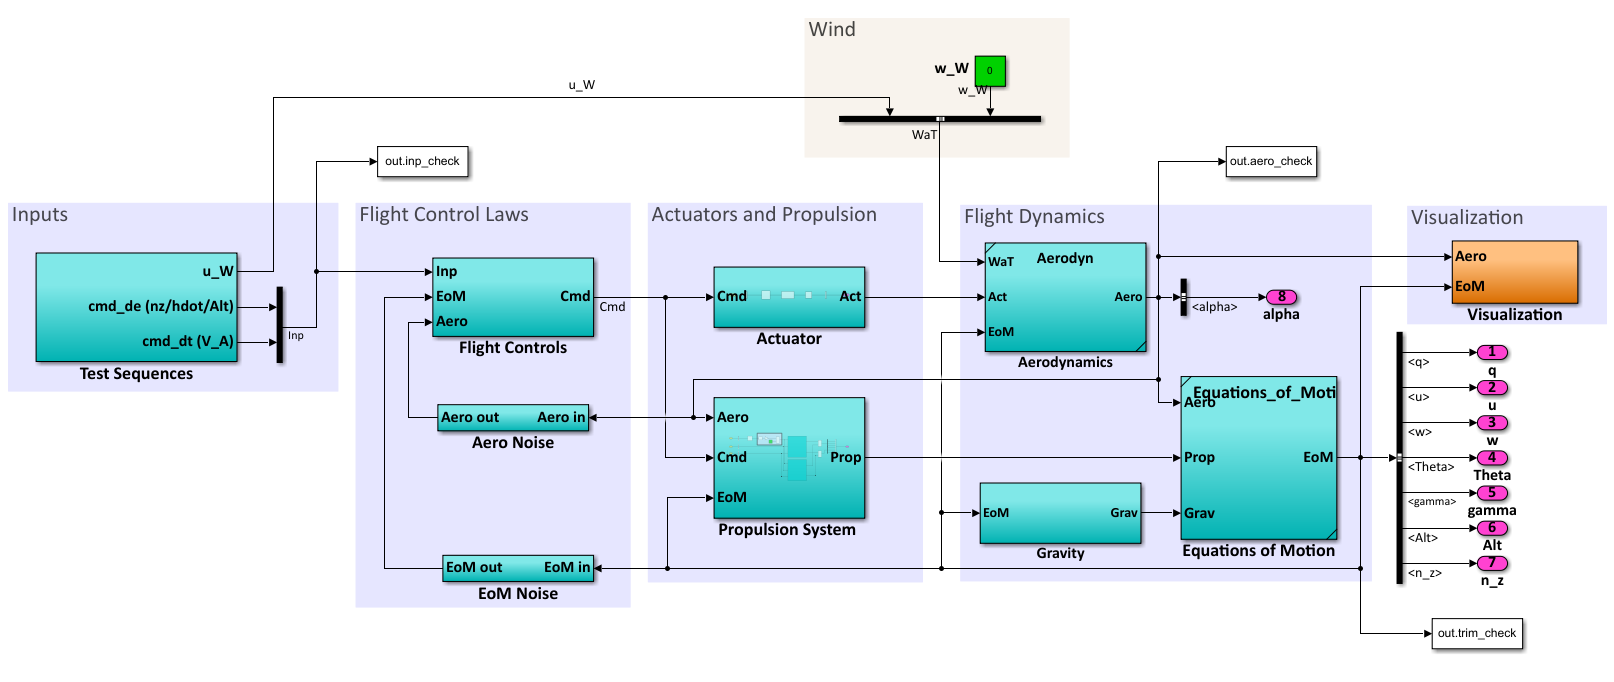

**Task 9:** implement the SAS controller

- implement the SAS controller 'F_q' in the 'Longitudinal Control Laws' subsystem and close the feedback loop. Choose the appropriate "controller module" from the 'Auxiliary_Models.slx' model and parameterize it (don't type in the value by hand! use 'ControlLaws.LonMot.SAS.F_q.d' instead!)

- ensure that the correct trim thrust lever position is issued to the engines

- add saturation blocks that limit both, the elevator deflection command (get the limits from 'AircraftParameters_Addition_LonMot.m') and the thrust lever position ($\delta_{\text{t,cmd}} \in [0 \ldots 1]$)

- **save** the augmented model **to a new file** named 'AircraftModel_LonMot_SAS.slx'

- simulate the aircraft's response using the subsequent code section

- it simulates a step input of $\delta_\text{e,cmd} = -1^^\circ$ elevator deflection after $t=5\,\text{s}$ and a horizontal so called "1-cos gust" of $|V_\text{W}| =20\,\text{m/s}$ gust speed with a duration of $15\,\text{s}$ beginning after $t=15\,\text{s}$. A "1-cos gust" is typically used in the aerospace community

- investigate the aircrafts response with and without the SAS active: compare the effect of the SAS on $q$, $w$, and $n_z$ 

**Check  **

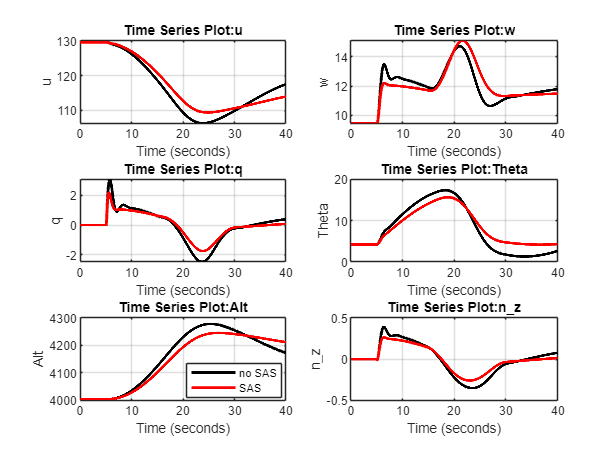

load 'ControlLaws.mat'
TestSequence = 1;
ControlLaws.LonMot.SAS.F_q.d = 0; % without SAS
[out] = sim('AircraftModel_LonMot_SAS.slx',40);
figure(340); clf
    subplot(3,2,1), plot(out.trim_check.vv_f.u,'k','linewidth',2)
    subplot(3,2,2), plot(out.trim_check.vv_f.w,'k','linewidth',2)
    subplot(3,2,3), plot(out.trim_check.q.*180/pi,'k','linewidth',2)
    subplot(3,2,4), plot(out.trim_check.Theta.*180/pi,'k','linewidth',2)
    subplot(3,2,5), plot(out.trim_check.Alt,'k','linewidth',2)
    subplot(3,2,6), plot(out.trim_check.nn_f.n_z,'k','linewidth',2)
    clear out
TestSequence = 1;
load("ControlLaws.mat") % with SAS
[out] = sim('AircraftModel_LonMot_SAS.slx',40);
  figure(340);
    subplot(3,2,1), hold on,  plot(out.trim_check.vv_f.u,'r','linewidth',2), grid on,
    subplot(3,2,2), hold on,  plot(out.trim_check.vv_f.w,'r','linewidth',2), grid on,
    subplot(3,2,3), hold on,  plot(out.trim_check.q.*180/pi,'r','linewidth',2), grid on,
    subplot(3,2,4), hold on,  plot(out.trim_check.Theta.*180/pi,'r','linewidth',2), grid on,
    subplot(3,2,5), hold on,  plot(out.trim_check.Alt,'r','linewidth',2), grid on, legend('no SAS','SAS', 'location','best')
    subplot(3,2,6), hold on,  plot(out.trim_check.nn_f.n_z,'r','linewidth',2), grid on

clear out
clf

**Incremental Load Factor Controller**

After you've modified the aircraft's dynamics through the SAS, you can now design the first primary flight controller for the longitudinal motion. That is, the inner most control loop of your longitudinal flight control architecture will control the incremental load factor $\Delta n_z$. Recall from the lecture that the load factor $n_z$ is the ratio of external forces and gravitational force acting on the aircraft, i.e., $n_z = -Z/mg $. The incremental load factor is $\Delta n_z = -(Z+mg \cos{\Theta})/mg$ . Note that the output 'n_z' in the nonlinear aircraft model is actually the incremental load factor $\Delta n_z$. Once again recall that the short period model 'SPModel_SAS' is a good approximation of the "true system" in the frequency range around the short period mode. That is, this model reflects the load factor dynamics with high accuracy and can be thus be used for the model based design of the control loop. Finally, you can apply the loopshaping design technique to design the controller 'Knz'.

Remark: we use the 'SPModel_SAS' here because the step response within the 'Control System Designer' app will be of higher resolution during the first $\approx 10\,\text{s}$. Compare the step responses of the 'SPModel_SAS' and the 'LinearLonModel_SAS' within the first $\approx 10\,\text{s}$ for yourself. 

**Task 10:** design the incremental load factor controller

- load the 'SPModel_SAS' into your workspace

- use the `controlSystemDesigner` command to investigate the transfer function from elevator input to 'n_z'. Note that to use the `controlSystemDesigner` command, the plant model must be single-input-single-output.

- choose the appropriate controller architecture from the 'Edit Architecture' menu

- close the root locus plot within the 'Control System Designer' app as it is not required to apply the loopshaping technique

- apply the loopshaping technique to design the incremental load factor controller

- once again, think about the sign of the P-gain.

- as an orientation, try to achieve the following: **1)** zero steady state error (note that this is only possible because we neglect the slower dynamics of the system)** 2)** settling time $(\pm 2\%)$$<3\,\text{s}$ ; **3)** overshoot $<10\%$, **4)** phase margin $PM>60^\circ$, **5)** gain margin $GM>6\,\text{db}$, **6) **$|L| >20\,\text{db}$ for $\omega < 0.1\,\text{rad/s}$ **7)**$|L|<-20\,\text{db}$ for $\omega > 10\,\text{rad/s}$

- integrate a roll-off filter 'Kr' that reduces the loop gain $|L|$ for frequencies above $30\,\text{rad/s}$

- uncomment the subsequent code section and augment it with the results you obtained in the 'Control System Designer' app - hint: the provided code can be used as a guideline, uncommend those controllers parts that you don't need

- run this section such that the 'ControlLaws'-struct will be augmented

- save the augmented 'ControlLaws'-struct (overwrite the existing 'ControlLaws.mat')

- **save the changes you've made within this livescript**

- check the loopshape of $|L|$ using the subsequent check section. Note that minor violations of the bounds are in general of no significant importance 

load TrimState_1_SPModel_SAS 
load ControlLaws
clear Kp Ki Kr Kl
% --------------------start of your code -------------------------- %

ControlLaws.LonMot.LoadFactor.Kp = 0.04; %0.049442;
ControlLaws.LonMot.LoadFactor.Ki = 5;
ControlLaws.LonMot.LoadFactor.Klz = 7; % lead/lag compensator: location of the zero wollte eigentlich nnoch eine lead einführen, aber zpk hat es leider nicht zugelassen.
ControlLaws.LonMot.LoadFactor.Klp = 7; % lead/lag compensator: location of the pole
ControlLaws.LonMot.LoadFactor.Kr = 30;
% 
s = tf('s');
% 
Kp = ControlLaws.LonMot.LoadFactor.Kp;
Kr = ControlLaws.LonMot.LoadFactor.Kr/(s+ControlLaws.LonMot.LoadFactor.Kr);
%Kl = (s + ControlLaws.LonMot.LoadFactor.Klz)/(s + 2.5*ControlLaws.LonMot.LoadFactor.Klp);
Ki = (s + ControlLaws.LonMot.LoadFactor.Ki)/s;
Knz = zpk(Ki*Kp*Kr); % e.g. zpk(Ki*Kr*Kl*Kp) if all controller parts are used
Knz = ss(Knz);
Knz.InputName = 'e_nz'; Knz.InputUnit = '-';
Knz.OutputName = 'cmd_de'; Knz.OutputUnit = 'rad';
Knz.StateName = {'K_nz','K_nz'};
Knz.StateUnit = {'rad','rad'};
ControlLaws.LonMot.LoadFactor.Knz = Knz;

% --------------------end of your code ---------------------------- %
clear Kp Ki Kr Kl

**Check**

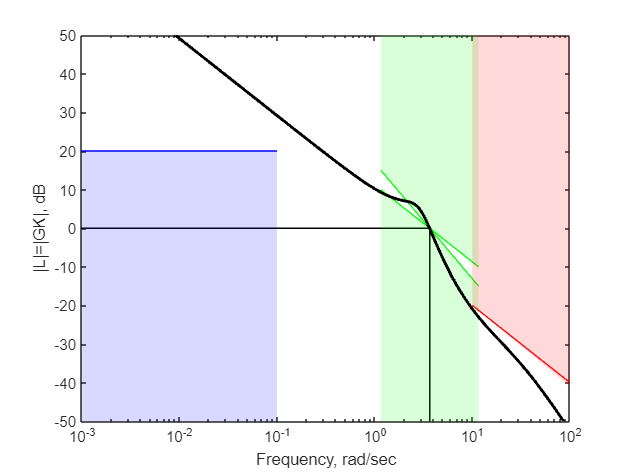

L = SPModel_SAS('n_z','cmd_de')*ControlLaws.LonMot.LoadFactor.Knz;
figure(350), clf, checkloopshape(L,20,0.1,-20,10)

**Task 11:** close the load factor feedback loop

- close the load factor feedback loop for both, the 'SPModel_SAS' and the 'LinearLonModel_SAS' using the `feedback` command. Make sure that the loop connects the correct model output to the correct model input. Hint: Use 'blkdiag()'.

- specify the input names of both signals to 'nz_cmd' and 'cmd_dt'

- name the newly created models 'SPModel_nz' and 'LinearLonModel_nz', respectively and save them to 'TrimState_1_LinearLonModel_nz.mat' and 'TrimState_1_SPModel_nz.mat'. Save them into the '3_LongitudinalControl' folder

- check the closed loop system reaction to a step input (magnitude of 'nz_cmd' is 0.2) using the subsequent check section

- check the second step response (from 'cmd_dt') to verify that you connected the controller correctly. There shouldn't be any strict command following in n_z - in contrast to the first step response from 'nz_cmd' (but of course there will be a reaction to a change in throttle position).


F_dummy = blkdiag([zeros(1,6),Knz,1; zeros(1,8)]);
LinearLonModel_nz = feedback(LinearLonModel_SAS, F_dummy)

LinearLonModel_nz =
 
  A = 
                   u           w           q       Theta         Alt          de         X_P        K_nz        K_nz
   u       -0.009033       11.76      -9.414      -9.784  -2.083e-05           0       2.728           0           0
   w      -0.0006107     -0.9668      0.9599   -0.005422   8.002e-06    -0.07428   -0.001095           0           0
   q        0.003614      -5.689      -1.152           0  -1.895e-06      -9.752    -0.09414           0           0
   Theta           0           0           1           0           0           0           0           0           0
   Alt       0.07213      -130.2           0       130.5           0           0           0           0           0
   de       0.009528      -17.19           0           0           0      -21.02           0       -28.2      -12.61
   X_P             0           0           0           0           0           0        -0.5           0           0
   K_nz            0           0   

SPModel_nz = feedback(SPModel_SAS, F_dummy)

SPModel_nz =
 
  A = 
             alpha         q        de       X_P      K_nz      K_nz
   alpha   -0.9716    0.9625  -0.07428  -0.00225         0         0
   q        -5.702    -1.145    -9.752  -0.09702         0         0
   de       -17.23  0.004954    -21.02         0     -28.2    -12.61
   X_P           0         0         0      -0.5         0         0
   K_nz          0         0         0         0         0     2.236
   K_nz      25.68    0.9878     1.977   0.02915         0       -30
 
  B = 
          cmd_de  cmd_dt
   alpha       0       0
   q           0       0
   de      21.02       0
   X_P         0     0.5
   K_nz        0       0
   K_nz        0       0
 
  C = 
               alpha           q          de         X_P        K_nz        K_nz
   q       -0.005323           1           0           0           0           0
   u          -7.489      0.6815           0           0           0           0
   w           130.3     0.01169           0           0   

**Check**

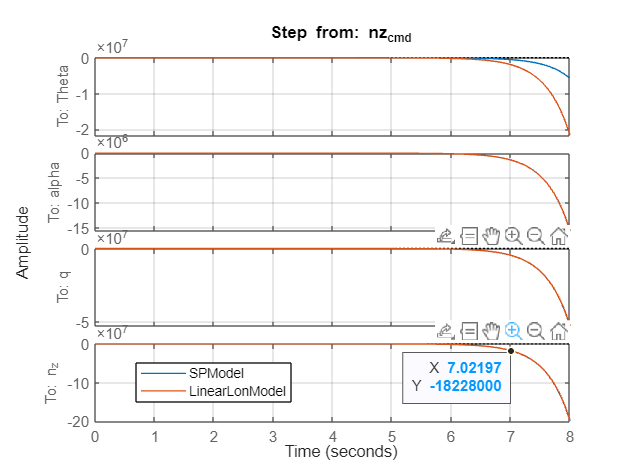

load TrimState_1_LinearLonModel_nz
load TrimState_1_SPModel_nz

figure(360), clf, step(SPModel_nz({'Theta','alpha','q','n_z'},'nz_cmd')*0.2,8), grid,...
hold on, step(LinearLonModel_nz({'Theta','alpha','q','n_z'},'nz_cmd')*0.2,8), ...
title('Step from: nz_{cmd}'),legend('SPModel','LinearLonModel','location','best')

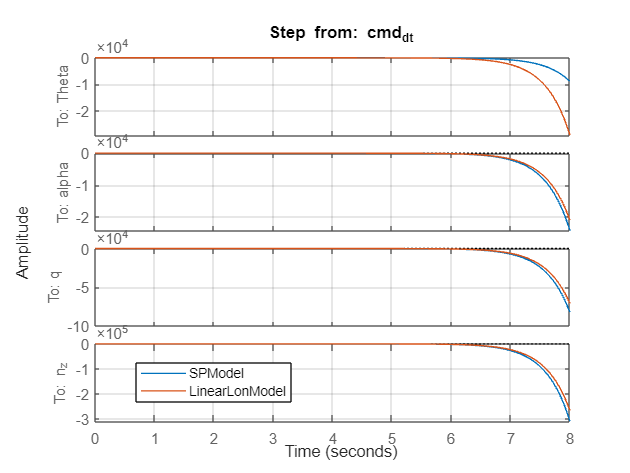

figure(361),clf, step(SPModel_nz({'Theta','alpha','q','n_z'},'cmd_dt')*0.5,8), grid
hold on, step(LinearLonModel_nz({'Theta','alpha','q','n_z'},'cmd_dt')*0.5,8),...
title('Step from: cmd_{dt}'),legend('SPModel','LinearLonModel','location','best')   

**Implementation of Incremental Load Factor Controller**

**Task 12:** implement the incremental load factor controller into the nonlinear aircraft simulation model

- open the 'AircraftModel_LonMot_SAS.slx' model and ensure that it is executable

- close the next feedback loop and implement the incremental load factor controller into the 'Flight Controls/Longitudinal Control Laws' subsystem - use the "controller modules" provided in the 'Auxiliary_Models.slx' model

- parameterize all blocks of the controller appropriately. Give every state within the 'Knz' controller the name 'Knz'

- initialize the last integrator in the series connection such that the trim elevator deflection is issued

- saturate the controller output such that the maximum and minium elevator deflections are limited as specified within the 'AircraftParameters_Addition_LonMot.m' Matlab script - don't use the 'Limit output' function of the integrator block!

- add anti-windup compensation using the 'Conditional Integration Anti Windup' block provided in the 'Auxiliary_Models.slx' model - **parameterize it** such that its limits fit the saturation of this control loop! Read the block's description in 'Auxiliary_Models.slx' for implementation details and follow them. 

- **save** the augmented model **to a new file** named 'AircraftModel_LonMot_nz.slx'

- simulate the aircraft's response using the subsequent check section - it simulates a load factor doublet command ( $n_{z,\text{cmd}} = +0.2\,g \rightarrow n_{z,\text{cmd}} = -0.2\,g \rightarrow n_{z,\text{cmd}} = 0\,g$) and a horizontal gust identical to the one used in **Task 9 **(starting 5 seconds later)

- investigate the aircraft response to the load factor command and the horizontal gust: does the load factor controller track the reference signal? What is the effect of the load factor controller during the gust? Especially focus on $n_z$ and $q$ here. If you implemented the controller correctly, the simulation results should be similar to the first step response in **Task 11** (keep in mind that the step response only considered linear models without wind gusts).

- Compare the aircraft response to the one of the stability augmented aircraft from **Task 9** (review the check after **Task 9)**.

**Check**

pause(1)
load 'ControlLaws.mat'

TestSequence = 2;

[out] = sim('AircraftModel_LonMot_nz.slx',40);
figure(370); clf
    subplot(3,2,1), plot(out.trim_check.vv_f.u,'k','linewidth',2), grid on, ...
    subplot(3,2,2), plot(out.trim_check.vv_f.w,'k','linewidth',2), grid on, ...
    subplot(3,2,3), plot(out.trim_check.q.*180/pi,'k','linewidth',2), grid on, ...
    subplot(3,2,4), plot(out.trim_check.Theta.*180/pi,'k','linewidth',2), grid on, ...
    subplot(3,2,5), plot(out.trim_check.Alt,'k','linewidth',2), grid on, ...
    subplot(3,2,6), plot(out.trim_check.nn_f.n_z,'k','linewidth',2), hold on, plot(out.inp_check.Time,out.inp_check.Data(:,1),'r--','linewidth',1.5), grid on
clear out

**Autothrottle Controller**

In order to track a reference airspeed or to attenuate disturbances, a feedback controller called 'autothrottle' can be designed to issue control signals to the propulsion system of the aircraft. In general, the airspeed $V_\text{A}$ is controlled by the autothrottle. From what we've learned so far, we know that the forward velocity $u$ (we assume that $V_\text{A} \approx u$) changes only slowly. Hence, the short period model is not an appropriate model for controller design anymore. We thus use the 'LinearLonModel_nz' to design the autothrottle 'Kathr'.

**Task 13:** design an autothrottle for the aircraft

- load the 'LinearModel_nz' into your workspace

- use the `controlSystemDesigner` command to investigate the transfer function from thrust lever input to the forward velocity.

- choose the appropriate controller architecture from the 'Edit Architecture' menu

- close the root locus plot within the 'Control System Designer' app as it is not required to apply the loopshaping technique

- apply the loopshaping technique to design the autothrottle

- as an orientation, try to achieve the following: **1)** zero steady state error** 2)** settling time $(\pm 2\%)$$<20\,\text{s}$ ; **3)** overshoot $<5\,\%$, **4)** phase margin $PM>60^\circ$, **5)** gain margin $GM>6\,\text{db}$, **6) **$|L| >20\,\text{db}$ for $\omega < 0.01\,\text{rad/s}$ **7)**$|L|<-20\,\text{db}$ for $\omega > 1\,\text{rad/s}$

- integrate a roll-off filter 'Kr' that reduces the loop gain $|L|$ for frequencies above $10\,\text{rad/s}$

- uncomment the subsequent code section and augment it with the results you obtained in the 'Control System Designer' app - hint: the provided code can be used as a guideline, comment out those controller stages that you don't need

- run this section such that the 'ControlLaws'-struct will be augmented

- save the augmented 'ControlLaws'-struct (overwrite the existing 'ControlLaws.mat')

- **save the changes you've made within this livescript**

- check the loopshape of $|L|$ using the subsequent check section. Note that minor violations of the bounds are in general of no significant importance 

load TrimState_1_LinearLonModel_nz
load ControlLaws
clear Kp Ki Kr Kl
% --------------------start of your code -------------------------- %

% ControlLaws.LonMot.ATHR.Kp = ...;
% ControlLaws.LonMot.ATHR.Ki = ...;
% ControlLaws.LonMot.ATHR.Klz = ...; % lead/lag compensator: location of the zero
% ControlLaws.LonMot.ATHR.Klp = ...; % lead/lag compensator: location of the pole
% ControlLaws.LonMot.ATHR.Kr = ...;
% 
% s = tf('s');
% 
% Kp = ControlLaws.LonMot.ATHR.Kp;
% Ki = (s + ControlLaws.LonMot.ATHR.Ki)/s;
% Kl = (s + ControlLaws.LonMot.ATHR.Klz)/(s + ControlLaws.LonMot.ATHR.Klp);
% Kr = ControlLaws.LonMot.ATHR.Kr/(s+ControlLaws.LonMot.ATHR.Kr);
% Kathr = zpk(...) % e.g. zpk(Ki*Kr*Kl*Kp) if all controller parts are used
% Kathr = ss(Kathr);
% Kathr.InputName = 'e_u'; Kathr.InputUnit = 'm/s';
% Kathr.OutputName = 'cmd_dt'; Kathr.OutputUnit = '-';
% Kathr.StateName = {'K_athr','K_athr'};
% ControlLaws.LonMot.ATHR.Kathr = Kathr;

% --------------------end of your code ---------------------------- %
clear Kp Ki Kr Kl

**Check**

L = LinearLonModel_nz('u','cmd_dt')*ControlLaws.LonMot.ATHR.Kathr;
figure(371), clf, checkloopshape(L,20,0.01,-20,1)

**Task 14:** close the forward velocity feedback loop

- close the forward velocity feedback loop for the 'LinearLonModel_nz' using the `feedback` command. Make sure that the loop connects the correct model output to the correct model input (use 'blkdiag()')

- specify the input names of both signals to 'nz_cmd' and 'Va_cmd'

- name the newly created model 'LinearLonModel_athr' and save it to 'TrimState_1_LinearLonModel_athr.mat'. Save it into the '3_LongitudinalControl' folder

- check the closed loop system reaction to a step input in the 'Va_cmd' (magnitude of 'Va_cmd' is 30) using the subsequent check section

- verfiy that you connected the controller correctly with the second step reponse from 'nz_cmd' (there should be no reference tracking of 'u' when commanding 'nz_cmd')

**Check**

load TrimState_1_LinearLonModel_athr
figure(372),clf; step(LinearLonModel_athr({'u','alpha'},'Va_cmd')*30,50), grid, legend('LinearLonModel','location','best'),title('Step from Va_{cmd}')
figure(373),clf; step(LinearLonModel_athr({'u','alpha'},'nz_cmd')*0.2,50), grid, legend('LinearLonModel','location','best'),title('Step from nz_{cmd}')

**Implement the Autothrottle**

**Task 15:** implement the autothrottle into the nonlinear aircraft simulation model

- open the 'AircraftModel_LonMot_nz.slx' model and ensure that it is executable

- close the next feedback loop and implement the autothrottle into the 'Flight Controls/Longitudinal Control Laws' subsystem - use the "controller modules" provided in the 'Auxiliary_Models.slx' model

- use the airspeed 'V_A' for feedback, not the forward velocity 'u' - recall that the transfer function used for controller designed is very similar to the loop you are about to close because $V_\text{A} \approx u$

- parameterize all blocks of the controller appropriately. Give every state within the 'Kathr' controller the name 'Kathr'

- initialize the last integrator in the series connection such that the trim thrust lever position is issued

- saturate the controller output such that the thrust lever position is limited to $[0 \ldots 1]$ - don't use the 'Limit output' function of the integrator block!

- add anti-windup compensation using the conditional integration anti-windup block provided in the 'Auxiliary_Models.slx' model - **parameterize it** such that its limits fit the saturation of this control loop! 

- **save** the augmented model **to a new file** named 'AircraftModel_LonMot_V_A.slx'

- simulate the aircraft's response using the subsequent check section - it simulates an airspeed command ( $V_{\text{A,cmd}} = \bar{V}_\text{A}+10\,\text{m/s}  \rightarrow V_{\text{A,cmd}} = \bar{V}_\text{A} \rightarrow V_\text{A,cmd} = \bar{V}_\text{A}-10\,\text{m/s}$) and a horizontal gust identical to the one used in **Task 12 **but starting at $t=100\,\text{s}$

- investigate the aircraft response to the airspeed reference signal and the horizontal gust: also compare the actual velocity peak during the gust with the maximum gust speed of $|V_\text{W}| = 20\,\text{m/s}$

**Check**

load 'ControlLaws.mat'

TestSequence = 3;

[out] = sim('AircraftModel_LonMot_V_A.slx',150);
figure(374); clf
    subplot(3,2,1), plot(out.aero_check.AirData.V_A,'k','linewidth',2), grid on, hold on, plot(out.inp_check.Time,out.inp_check.Data(:,2),'r--','linewidth',1),
    subplot(3,2,2), plot(out.trim_check.vv_f.w,'k','linewidth',2), grid on, ...
    subplot(3,2,3), plot(out.trim_check.q.*180/pi,'k','linewidth',2), grid on, ...
    subplot(3,2,4), plot(out.trim_check.Theta.*180/pi,'k','linewidth',2), grid on, ...
    subplot(3,2,5), plot(out.trim_check.Alt,'k','linewidth',2), grid on, ...
    subplot(3,2,6), plot(out.trim_check.nn_f.n_z,'k','linewidth',2), grid on
clear out

**Clim Rate Controller**

A very usefull controller that is frequently used by pilots is the *vertical speed* or *climb rate *controller. This controller is usually considered to be the first "real autopilot controller" as its reference signals are usually not provided directly via a sidestick or yoke. The climb rate is the aircraft's velocity perpendicular to the earth's surface, i.e.$\dot{h} = -w_g$. Hence, it is different from the output signal of the linearized aircraft model which is $w_f$. In order to design a climb rate controller, we thus need to modify the output of the linear model. To do this, we first linearize the nonlinear differential equation $\dot{h} = \sin(\Theta)\,u_f - \cos(\Theta)\,w_f$ at the trim point. We then create a new output matrix $\tilde{C} = \hat{C}C$, where $C$ is the "original" C-matrix and $\hat{C}$ is the applied transformation. This is done in the subsequent code section. Note that only the $3^{rd}$ output is modified while the rest is left unchanged. Linearize $\dot{h}$ for yourself to check the entries in the transformation matrix $\hat{C}$. 

C_hat = [1 0 0 0 0 0 0 0; ...
         0 1 0 0 0 0 0 0; ...
         0 sin(TrimPoint.States.Thetabar) -cos(TrimPoint.States.Thetabar) (sin(TrimPoint.States.Thetabar)*TrimPoint.States.wbar + cos(TrimPoint.States.Thetabar)*TrimPoint.States.ubar) 0 0 0 0; ...
         0 0 0 1 0 0 0 0; ...
         0 0 0 0 1 0 0 0; ...
         0 0 0 0 0 1 0 0; ...
         0 0 0 0 0 0 1 0; ...
         0 0 0 0 0 0 0 1]
load TrimState_1_LinearLonModel_athr.mat
LinearLonModel_athr = C_hat*LinearLonModel_athr;
LinearLonModel_athr.OutputName = LinearLonModel.OutputName;
LinearLonModel_athr.OutputName{3} = 'hdot';

**Task 16:** design an climb rate controller for the aircraft

- load the 'LinearModel_athr' into your workspace

- use the `controlSystemDesigner` command to investigate the transfer function from 'nz_cmd' to the climb rate

- choose the appropriate controller architecture from the 'Edit Architecture' menu

- apply the loopshaping technique to design the climb rate controller

- as an orientation, try to achieve the following: **1)** zero steady state error** 2)** settling time $(\pm 2\%)$$<6\,\text{s}$ ; **3)** overshoot $<5\,\%$, **4)** rise time (to $63\,\%$) $<1.5\,\text{s}$ **5) **phase margin $PM>60^\circ$, **6)** gain margin $GM>6\,\text{db}$, **7) **$|L| >30\,\text{db}$ for $omega < 0.01\,\text{rad/s}$ **8)**$|L|<20\,\text{db}$ for $\omega > 10\,\text{rad/s}$

- integrate a roll-off filter 'Kr' that reduces the loop gain $|L|$ for frequencies above $30\,\text{rad/s}$

- uncomment the subsequent code section and augment it with the results you obtained in the 'Control System Designer' app - hint: the provided code can be used as a guideline, comment out those controller stages that you don't need

- run this section such that the 'ControlLaws'-struct will be augmented

- save the augmented 'ControlLaws'-struct (overwrite the existing 'ControlLaws.mat')

- **save the changes you've made within this livescript**

- check the loopshape of $|L|$ using the subsequent check section. Note that minor violations of the bounds are in general of no significant importance 

load ControlLaws
clear Kp Ki Kr Kl
% --------------------start of your code -------------------------- %

% ControlLaws.LonMot.ClimbRate.Kp = ...;
% ControlLaws.LonMot.ClimbRate.Ki = ...;
% ControlLaws.LonMot.ClimbRate.Klz = ...; % lead/lag compensator: location of the zero
% ControlLaws.LonMot.ClimbRate.Klp = ...; % lead/lag compensator: location of the pole
% ControlLaws.LonMot.ClimbRate.Kr = ...;
% 
% s = tf('s');
% 
% Kp = ControlLaws.LonMot.ClimbRate.Kp;
% Ki = (s + ControlLaws.LonMot.ClimbRate.Ki)/s;
% Kl = (s + ControlLaws.LonMot.ClimbRate.Klz)/(s + ControlLaws.LonMot.ClimbRate.Klp);
% Kr = ControlLaws.LonMot.ClimbRate.Kr/(s+ControlLaws.LonMot.ClimbRate.Kr);
% Khdot = zpk(...) % e.g. zpk(Ki*Kr*Kl*Kp) if all controller parts are used
% Khdot = ss(Khdot);
% Khdot.InputName = 'e_hdot'; Khdot.InputUnit = 'm/s';
% Khdot.OutputName = 'nz_cmd'; Khdot.OutputUnit = '-';
% Khdot.StateName = {'K_hdot'};
% ControlLaws.LonMot.ClimbRate.Khdot = Khdot;
% ControlLaws.Saturations.nz = [-1 2]; % specify limits for the incremental load factor command

% --------------------end of your code ---------------------------- %
clear Kp Ki Kr Kl

**Check**

L = LinearLonModel_athr('hdot','nz_cmd')*ControlLaws.LonMot.ClimbRate.Khdot;
figure(375), clf, checkloopshape(L,30,0.01,-20,10)

**Task 17:** close the climb rate feedback loop

- close the climb rate feedback loop for the (transformed) 'LinearLonModel_athr' using the `feedback` command. Make sure that the loop connects the correct model output to the correct model input (use 'blkdiag()')

- specify the input names of both signals to 'hdot_cmd' and 'Va_cmd'

- name the newly created model 'LinearLonModel_hdot' and save it to 'TrimState_1_LinearLonModel_hdot.mat'. Save it into the '3_LongitudinalControl' folder

- check the closed loop system reaction to a step input in the 'hdot_cmd' using the subsequent check section

- verfiy that you connected the controller correctly with the second step reponse from 'Va_cmd' (there should be no reference tracking of 'hdot' from the input 'hdot_cmd')

**Check**

load TrimState_1_LinearLonModel_hdot
figure(376),clf; step(LinearLonModel_hdot({'Theta','q','hdot'},'hdot_cmd')*1,8),title('Step from hdot_{cmd}'),legend('LinearLonModel','location','best'), grid,...
figure(377),clf; step(LinearLonModel_hdot({'Theta','q','hdot'},'Va_cmd')*30,8),title('Step from Va_{cmd}'),...
legend('LinearLonModel','location','best'), grid

**Implement the Climb Rate Controller**

**Task 15:** implement the climb rate controller into the nonlinear aircraft simulation model

- open the 'AircraftModel_LonMot_V_A.slx' model and ensure that it is executable

- close the next feedback loop and implement the autothrottle into the 'Flight Controls/Longitudinal Control Laws' subsystem - use the "controller modules" provided in the 'Auxiliary_Models.slx' model

- make sure to feed back $\dot{h}$ to the control loop! Create it from already existing signals within the nonlinear aircraft model

- parameterize all blocks of the controller appropriately. Give every state within the controller the name 'Khdot'

- saturate the controller output such that the incremental load factor command is limited to $[-1 \ldots 2]$ - don't use the 'Limit output' function of the integrator block!

- in case of integral control: add anti-windup compensation using the conditional integration anti-windup block provided in the 'Auxiliary_Models.slx' model - **parameterize it** such that its limits fit the saturation of this control loop!

- **save** the augmented model **to a new file** named 'AircraftModel_LonMot_hdot.slx'

- simulate the aircraft's response using the subsequent check section - it simulates a climb rate doublet command ( $\dot{h}_{\text{cmd}} = 5\,\text{m/s}  \rightarrow \dot{h}_{\text{cmd}} = -5\,\text{m/s}\rightarrow \dot{h}_{\text{cmd}} = 0\,\text{m/s}$) and a horizontal gust identical to the one used in **Task 12 **but starting at $t=100\,\text{s}$

- investigate the aircraft response to the climb rate reference signal and the horizontal gust: also compare the actual velocity peak during the gust with the maximum gust speed of $|V_\text{W}| = 20\,\text{m/s}$

**Check**

load 'ControlLaws.mat'

TestSequence = 4;

[out] = sim('AircraftModel_LonMot_hdot.slx',50);

Alt_cmd = cumtrapz(out.inp_check.Time,out.inp_check.Data(:,1)) + TrimPoint.States.Altbar; % integrate climb rate command to compute corresponding altitude command

figure(376); clf
    subplot(3,2,1), plot(out.trim_check.vv_f.u,'k','linewidth',2), grid on,
    subplot(3,2,2), plot(out.trim_check.vv_f.w,'k','linewidth',2), grid on,
    subplot(3,2,3), plot(out.trim_check.q.*180/pi,'k','linewidth',2), grid on, ...
    subplot(3,2,4), plot(out.trim_check.Theta.*180/pi,'k','linewidth',2), grid on, ...
    subplot(3,2,5), plot(out.trim_check.Alt,'k','linewidth',2), grid on, hold on, plot(out.inp_check.Time,Alt_cmd,'r--','linewidth',2),
    subplot(3,2,6), plot(out.trim_check.nn_f.n_z,'k','linewidth',2), grid on
clear out Alt_cmd

**Altitude Controller**

The altitude controller is part of the autopilot system of an aircraft and frequently used by pilots. Moreover, the reference to the altitude controller can not only be set by the pilots but also be computed by an additional outer system usually called *flight management system* (FMS). We will not address this FMS but instead focus on the altitude control law as the final control loop that completes the longitudinal flight control system.

**Task 16:** design an altitude controller for the autopilot system of the aircraft

- load the 'LinearModel_hdot' into your workspace

- use the `controlSystemDesigner` command to investigate the transfer function from climb rate command to altitude

- choose the appropriate controller architecture from the 'Edit Architecture' menu

- apply the loopshaping technique to design the altitude controller

- as an orientation, try to achieve the following: **1)** zero steady state error** 2)** settling time $(\pm 2\%)$$<10\,\text{s}$ ; **3)** overshoot $<2\,\%$, **4)** phase margin $PM>60^\circ$, **6)** gain margin $GM>6\,\text{db}$, **7) **$|L| >20\,\text{db}$ for $\omega < 0.04\,\text{rad/s}$ **8)**$|L|<-20\,\text{db}$ for $\omega > 5\,\text{rad/s}$

- integrate a roll-off filter 'Kr' that reduces the loop gain $|L|$ for frequencies above $20\,\text{rad/s}$

- uncomment the subsequent code section and augment it with the results you obtained in the 'Control System Designer' app - hint: the provided code can be used as a guideline, comment out those controller stages that you don't need

- run this section such that the 'ControlLaws'-struct will be augmented

- save the augmented 'ControlLaws'-struct (overwrite the existing 'ControlLaws.mat')

- **save the changes you've made within this livescript**

- check the loopshape of $|L|$ using the subsequent check section. Note that minor violations of the bounds are in general of no significant importance 

load TrimState_1_LinearLonModel_hdot
load ControlLaws
clear Kp Ki Kr Kl
% --------------------start of your code -------------------------- %

% ControlLaws.LonMot.Altitude.Kp = ...;
% ControlLaws.LonMot.Altitude.Ki = ...;
% ControlLaws.LonMot.Altitude.Klz = ...; % lead/lag compensator: location of the zero
% ControlLaws.LonMot.Altitude.Klp = ...; % lead/lag compensator: location of the pole
% ControlLaws.LonMot.Altitude.Kr = ...;
% 
% s = tf('s');
% 
% Kp = ControlLaws.LonMot.Altitude.Kp;
% Ki = (s + ControlLaws.LonMot.Altitude.Ki)/s;
% Kl = (s + ControlLaws.LonMot.Altitude.Klz)/(s + ControlLaws.LonMot.Altitude.Klp);
% Kr = ControlLaws.LonMot.Altitude.Kr/(s+ControlLaws.LonMot.Altitude.Kr);
% Kalt = zpk(...) % e.g. zpk(Ki*Kr*Kl*Kp) if all controller parts are used
% Kalt = ss(Kalt);
% Kalt.InputName = 'e_alt'; Kalt.InputUnit = 'm';
% Kalt.OutputName = 'hdot_cmd'; Kalt.OutputUnit = 'm/s';
% Kalt.StateName = {'K_alt'};
% ControlLaws.LonMot.Altitude.Kalt = Kalt;
% ControlLaws.Saturations.hdot = [-10 10]; % specify limits for the incremental load factor command

% --------------------end of your code ---------------------------- %
clear Kp Ki Kr Kl

**Check**

L = LinearLonModel_hdot('alt','hdot_cmd')*ControlLaws.LonMot.Altitude.Kalt;
figure(380), clf, checkloopshape(L,20,0.04,-20,5)

**Task 17:** close the altitude feedback loop

- close the altitude feedback loop for the 'LinearLonModel_hdot' model using the `feedback` command. Make sure that the loop connects the correct model output to the correct model input (use 'blkdiag()')

- specify the input names of both signals to 'alt_cmd' and 'Va_cmd'

- name the newly created model 'LinearLonModel_alt' and save it to 'TrimState_1_LinearLonModel_alt.mat'. Save it into the '3_LongitudinalControl' folder

- check the closed loop system reaction to a step input in the 'alt_cmd' (magnitude $150\,\text{m}$) using the subsequent check section

- assume that the step responses are close to the real world behaviour of the aircraft: would you like to sit in this aircraft? Investigate the climb rate command. What do the step responses reveal w.r.t. control signal limitations?

- verfiy that you connected the controller correctly with the second step reponse from 'Va_cmd' (there should be no reference tracking of 'alt_cmd' from the control input 'Va_cmd')

**Check**

load TrimState_1_LinearLonModel_alt
figure(381),clf; step(LinearLonModel_alt({'Theta','hdot','alt'},'alt_cmd')*150,25), title('Step from alt_{cmd}'), legend('LinearLonModel','location','best'), grid,...
figure(382),clf; step(LinearLonModel_alt({'Theta','hdot','alt'},'Va_cmd')*30,25), title('Step from Va_{cmd}'), legend('LinearLonModel','location','best'), grid  

**Implement the Altitude Controller**

**Task 18:** implement the altitude controller into the nonlinear aircraft simulation model

- open the 'AircraftModel_LonMot_hdot.slx' model and ensure that it is executable

- close the next feedback loop and implement the altitude controller into the 'Flight Controls/Longitudinal Control Laws' subsystem - use the 

- "controller modules" provided in the 'Auxiliary_Models.slx' model

- parameterize all blocks of the controller appropriately. Give every state within the controller the name 'Kalt'

- saturate the controller output such that the climb rate command is limited to $[-10 \ldots 10]\,\text{m/s}$ - don't use the 'Limit output' function of the integrator block!

- in case of integral control: add anti-windup compensation using the conditional integration anti-windup block provided in the 'Auxiliary_Models.slx' model - **parameterize it** such that its limits fit the saturation of this control loop!

- **save** the augmented model **to a new file** named 'AircraftModel_LonMot_Alt.slx'

- simulate the aircraft's response using the subsequent check section - it simulates a changing altitude command ( $h_{\text{cmd}} = \bar{h}+100\,\text{m}  \rightarrow h_{\text{cmd}} = \bar{h} - 100\,\text{m} \rightarrow h_\text{cmd} = \bar{h}$) and a varying airspeed reference. Further, a horizontal 1-cos-gust of $|V_\text{W}|=20\,\text{m/s}$ affects the aircraft after $t=30\,\text{s}$ for $t=15\,\text{s}$

- investigate the aircraft response to the autopilot reference signals. Check whether yout autopilots achieve reference tracking. 

**Congratulations! You completed the longitudinal flight control system design process! **

**Check**

load 'ControlLaws.mat'

TestSequence = 5;

[out] = sim('AircraftModel_LonMot_Alt.slx',150);

figure(382); clf
    subplot(3,2,1), plot(out.aero_check.AirData.V_A,'k','linewidth',2), hold on, plot(out.inp_check.Time,out.inp_check.Data(:,2),'r--','linewidth',1), grid on
    subplot(3,2,2), plot(out.trim_check.vv_f.w,'k','linewidth',2), grid on
    subplot(3,2,3), plot(out.trim_check.q.*180/pi,'k','linewidth',2), grid on
    subplot(3,2,4), plot(out.trim_check.Theta.*180/pi,'k','linewidth',2), grid on
    subplot(3,2,5), plot(out.trim_check.Alt,'k','linewidth',2), hold on, plot(out.inp_check.Time,out.inp_check.Data(:,1),'r--','linewidth',1), grid on
    subplot(3,2,6), plot(out.trim_check.nn_f.n_z,'k','linewidth',2), grid on
clear out

**Controller Performace Investigation**

**Optional Task: **investigate the aircraft's response to arbitrary input signals 

- open the 'AircraftModel_LonMot_Alt.slx' model and ensure that it is executable 

- create a new model named 'AircraftModel_LonMot_optional.slx' and save it

- apply (multiple and simultaneous) arbitrary input signals and investigate the aircraft's response to different disturbances (in 'u_w' and 'w_W')

- load another trim state from Part I and check the performance and robustness of your controllers

- try to find out performace limitations

% end of file 